# WKB expansion for a fractional Schrödinger equation

In the particular case under analysis, the construction that we obtain is then applied to the study of controllability properties for the one dimensional fractional Schrödinger equation.


$$\begin{cases} 		iu_t+ (-d_x^2)^s u = g\chi_{\omega\times(0,T)}, & (x,t)\in (-1,1)\times(0,T) 		\\ 		u\equiv 0, & (x,t)\in(-1,1)^c\times(0,T) 		\\ 		u(x,0)=u_0(x), & x\in(-1,1), 	\end{cases}$$


With highly oscillatory initial datum


$$u_0(x) = e^{-\frac \gamma2 (x-x_0)^2}e^{i\frac {\xi_0}{\varepsilon} x}$$


Nx = 400;
L = 1;
hx = (2*L)/(Nx+1);

Now, we can be define the function_handle u0, from before data.

x0 = 0;
fr = pi^2/16;
gamma = hx^(-0.9);
%
u0 = @(x) exp(-0.5*gamma*(x-x0).^2).*exp(1i*fr*x/hx);

Can see the representation of initial Datum 

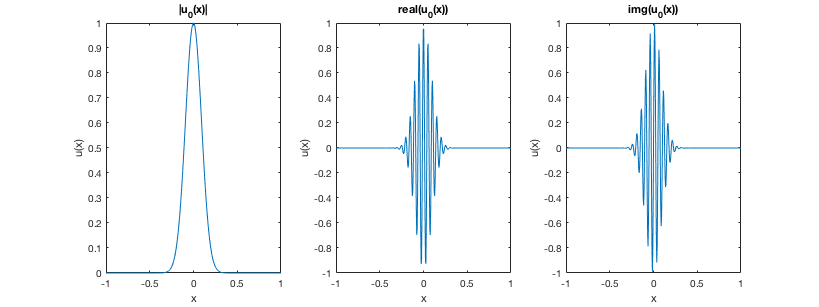

set(gcf,'Units','normalized','Position',[0.1 0.1 0.6 0.4])
x = -L:hx:L;
%
subplot(1,3,1)
plot(x,abs(u0(x)))
title('|u_0(x)|')
xlabel('x'); ylabel('u(x)');
%
subplot(1,3,2)
plot(x,real(u0(x)))
title('real(u_0(x))')
xlabel('x'); ylabel('u(x)');

%
subplot(1,3,3)
plot(x,imag(u0(x)))
title('img(u_0(x))')
xlabel('x'); ylabel('u(x)');

## Solution for s = 1/2 

To solve this equation, Need define the next parameters;

s   = 0.5  % Laplacian Order

s = 0.5000

L          % x in (-L , L)

L = 1

Nx         % Number of points in space

Nx = 400

T   = 5    % Final time

T = 5

And u0 is the function_handle, that have showed before. Now call the function **fractional_schr** to solve the equation.

[x,t,u] = fractional_schr(s,L,Nx,T,u0)

x =    -1.0000   -0.9950   -0.9900   -0.9850   -0.9800   -0.9751   -0.9701   -0.9651   -0.9601   -0.9551   -0.9501   -0.9451   -0.9401   -0.9352   -0.9302   -0.9252   -0.9202   -0.9152   -0.9102   -0.9052   -0.9002   -0.8953   -0.8903   -0.8853   -0.8803   -0.8753   -0.8703   -0.8653   -0.8603   -0.8554   -0.8504   -0.8454   -0.8404   -0.8354   -0.8304   -0.8254   -0.8204   -0.8155   -0.8105   -0.8055   -0.8005   -0.7955   -0.7905   -0.7855   -0.7805   -0.7756   -0.7706   -0.7656   -0.7606   -0.7556


t =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0204    0.0209    0.0214    0.0219    0.0224    0.0229    0.0234    0.0239    0.0244


u =    1.0e-09 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000    0.0090    0.0183    0.0279    0.0377    0.0478    0.0580    0.0683    0.0788    0.0893    0.0998    0.1104    0.1209    0.1314    0.1418    0.1521    0.1623    0.1725    0.1825    0.1924    0.2023    0.2120    0.2217    0.2313    0.2409    0.2504    0.2599    0.2695    0.2790    0.2885    0.2981    0.3078    0.3174    0.3272    0.3370    0.3469    0.3568    0.3668    0.3769    0.3870    0.3972    0.4074    0.4177    0.4280    0.4384    0.4488    0.4592    0.4697 

Obtain the $u(x,t) $in u variable

Now we can see a graphical interpretation

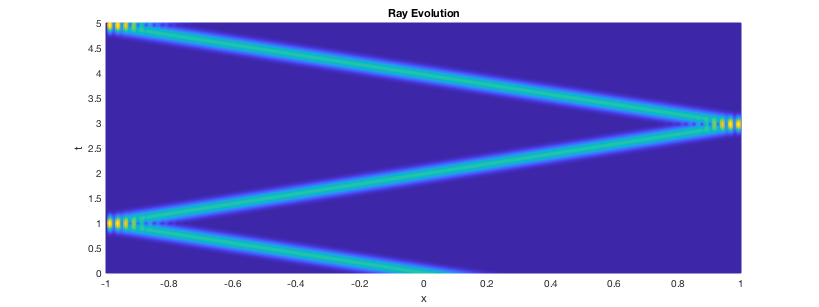

[X ,T] = meshgrid(x,t);
%
clf
mesh(X,T,u')
view(0,90)
xlabel('x'); ylabel('t'); title('Ray Evolution');

For last, if you type "*animation(x,t,u)*", in MATLAB console. You can see the evolution in time of this wave.